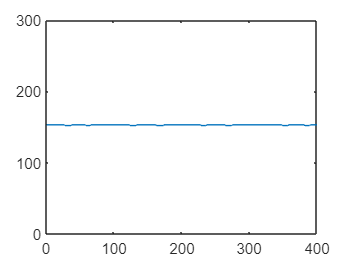

clear all

threshold=0;

biomass_3000_0(1:400,1:400)=0.0;
run('D45000_Cn5_5e_6noise0Khill0_01_dt0_05_at15500.m')

interface_Xcoordinate(1:400)=1;

for x=2:400
    for y=1:400
        if abs(biomass_15500_0(x-1,y)-biomass_15500_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

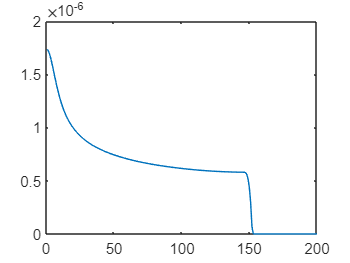



for x=1:400
    biomass(x)=0.0;
    for y=1:400
        biomass(x)=biomass(x)+biomass_15500_0(x,y)/400;
    end
end

plot(biomass(1:200));



Roughness=std(interface_Xcoordinate)

Roughness = 0.3867

R(1)=Roughness

R = 0.3867


biomass_4600_0(1:300,1:300)=0.0;
run('FinalBiomassFiles/biomass_k1_D06_4600.m')

Error using run
FinalBiomassFiles\biomass_k1_D06_4600.m not found.


interface_Xcoordinate(1:100)=1;

for x=2:300
    for y=1:300
        if abs(biomass_4600_0(x-1,y)-biomass_4600_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

Roughness=std(interface_Xcoordinate)
R(2)=Roughness;


biomass_3200_0(1:300,1:300)=0.0;
run('FinalBiomassFiles/biomass_k1_D10_3200.m')


interface_Xcoordinate(1:100)=1;

for x=2:300
    for y=1:300
        if abs(biomass_3200_0(x-1,y)-biomass_3200_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

Roughness=std(interface_Xcoordinate)
R(3)=Roughness;


biomass_10000_0(1:300,1:300)=0.0;
run('FinalBiomassFiles/biomass_k1_D14_10000.m')


interface_Xcoordinate(1:100)=1;

for x=2:300
    for y=1:300
        if abs(biomass_10000_0(x-1,y)-biomass_10000_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

Roughness=std(interface_Xcoordinate)
R(4)=Roughness;


biomass_10000_0(1:300,1:300)=0.0;
run('FinalBiomassFiles/biomass_k1_D18_10000.m')
 
 interface_Xcoordinate(1:100)=1;

for x=2:300
    for y=1:300
        if abs(biomass_10000_0(x-1,y)-biomass_10000_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

Roughness=std(interface_Xcoordinate)
R(5)=Roughness;

 
 biomass_10000_0(1:300,1:300)=0.0;
run('FinalBiomassFiles/biomass_k1_D22_10000.m')
 
 interface_Xcoordinate(1:100)=1;

for x=2:300
    for y=1:300
        if abs(biomass_10000_0(x-1,y)-biomass_10000_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

Roughness=std(interface_Xcoordinate)
R(6)=Roughness;

biomass_8500_0(1:300,1:300)=0.0;
 run('FinalBiomassFiles/biomass_k1_D26_8500')
 
 interface_Xcoordinate(1:100)=1;

for x=2:300
    for y=1:300
        if abs(biomass_8500_0(x-1,y)-biomass_8500_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

Roughness=std(interface_Xcoordinate)
R(7)=Roughness;
R(7)=0;

 biomass_8000_0(1:300,1:300)=0.0;
run('FinalBiomassFiles/biomass_k1_D30_8000.m')
 
 interface_Xcoordinate(1:100)=1;

for x=2:300
    for y=1:300
        if abs(biomass_8000_0(x-1,y)-biomass_8000_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

Roughness=std(interface_Xcoordinate)
R(8)=Roughness;



plot(0.2:0.4:3.0,R,'o-')
xlim([0 3.2])
xlabel('D')
ylabel('Propagating Interface Roughness')
R